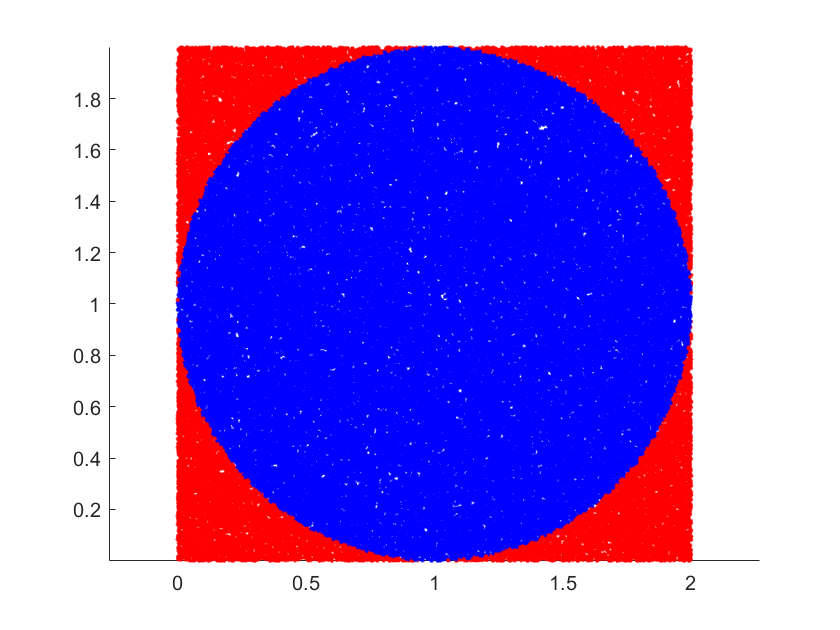

p = 100000; 
r = 1;
x0 = 1;
y0 = 1;
n = 0;
hold on
for i = 1:p
    px = rand*2;
    py = rand*2;
    if (px - 1)^2 + (py - 1)^ 2 < 1
        plot(px,py,'.','Color',"b");
        n = n + 1;
    else
        plot(px,py,'.','Color',"r");
    end
end
axis equal

s = (n/p)*4;
pi0 = s

pi0 = 3.1389

## 三门问题

考虑失败情况的代码（无条件概率）

clear;clc % 考虑失败情况的代码（无条件概率）
%randi([1,5],5,8)    % 在区间[1,5]内随机取出大小为5*8的整数矩阵
%randi([1,5])        % 在区间[1,5]内随机取出1个整数
n = 100000;
a = 0;
b = 0;
c = 0;
for i= 1: n
    x = randi([1,3]);
    y = rand([1,3]);
    change = randi([0,1]);
    if x==y
        if change == 0
            a = a + 1;
        else
            c = c + 1
        end
    else
        if change == 0
            c = c + 1;
        else
            b = b + 1;
        end
    end
end
disp(['蒙特卡罗方法得到的不改变注意时的获奖概率为： ',num2str(a/n)]);

蒙特卡罗方法得到的不改变注意时的获奖概率为： 0


disp(['蒙特卡罗方法得到的改变注意时的获奖概率为： ',num2str(b/n)]);

蒙特卡罗方法得到的改变注意时的获奖概率为： 0.50111


disp(['蒙特卡罗方法得到的没有获奖概率为： ',num2str(c/n)]);

蒙特卡罗方法得到的没有获奖概率为： 0.49889


## 在成功的条件下的概率

n = 100000;
a = 0;
b = 0;
for i = 1:n
    x = randi([1,3]);
    y = randi([1,3]);
    if x == y
        a = a + 1;
        b = b + 0;
    else
        a = a + 0;
        b = b + 1;
    end
end
disp(['蒙特卡罗方法得到的不改变注意时的获奖概率为： ',num2str(a/n)]);

蒙特卡罗方法得到的不改变注意时的获奖概率为： 0.33319


disp(['蒙特卡罗方法得到的改变注意时的获奖概率为： ',num2str(b/n)]);

蒙特卡罗方法得到的改变注意时的获奖概率为： 0.66681
